# Cinematica inversa manipolatore di Stanford

## Manipolatore di Stanford

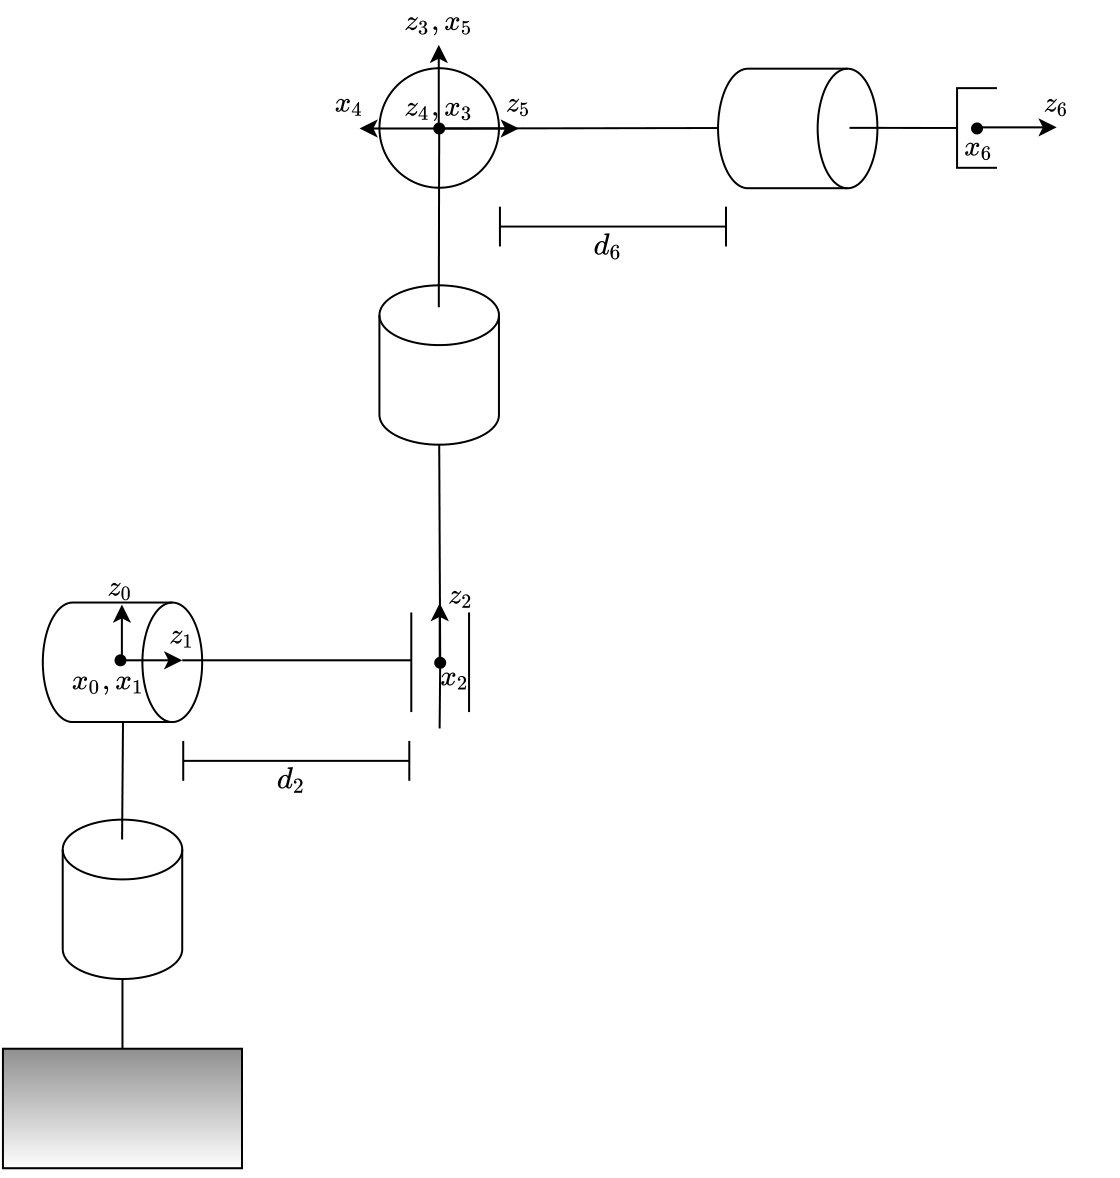

syms q1 q2 q3 q4 q5 q6 d2 d6 real
DHstanford = [0, -pi/2, 0, q1;
             0, pi/2, d2, q2;
             0, 0, q3, 0;
             0, -pi/2, 0, q4;
             0, pi/2, 0, q5;
             0, 0, d6, q6]

$$DHstanford = \left(\begin{array}{cccc} 0 & -\frac{\pi }{2} & 0 & q_{1}\\ 0 & \frac{\pi }{2} & d_{2} & q_{2}\\ 0 & 0 & q_{3} & 0\\ 0 & -\frac{\pi }{2} & 0 & q_{4}\\ 0 & \frac{\pi }{2} & 0 & q_{5}\\ 0 & 0 & d_{6} & q_{6} \end{array}\right)$$

TstanfordList = cinDirDH(DHstanford);
T01 = TstanfordList{1};
T12 = TstanfordList{2};
T23 = TstanfordList{3};
T34 = TstanfordList{4};
T45 = TstanfordList{5};
T56 = TstanfordList{6};
T03 = T01*T12*T23

$$T03 = \left(\begin{array}{cccc} \cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & -\sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & q_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)-d_{2}\,\sin\left(q_{1}\right)\\ \cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & d_{2}\,\cos\left(q_{1}\right)+q_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ -\sin\left(q_{2}\right) & 0 & \cos\left(q_{2}\right) & q_{3}\,\cos\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T36 = T34*T45*T56

$$T36 = \left(\begin{array}{cccc} \cos\left(q_{4}\right)\,\cos\left(q_{5}\right)\,\cos\left(q_{6}\right)-\sin\left(q_{4}\right)\,\sin\left(q_{6}\right) & -\cos\left(q_{6}\right)\,\sin\left(q_{4}\right)-\cos\left(q_{4}\right)\,\cos\left(q_{5}\right)\,\sin\left(q_{6}\right) & \cos\left(q_{4}\right)\,\sin\left(q_{5}\right) & d_{6}\,\cos\left(q_{4}\right)\,\sin\left(q_{5}\right)\\ \cos\left(q_{4}\right)\,\sin\left(q_{6}\right)+\cos\left(q_{5}\right)\,\cos\left(q_{6}\right)\,\sin\left(q_{4}\right) & \cos\left(q_{4}\right)\,\cos\left(q_{6}\right)-\cos\left(q_{5}\right)\,\sin\left(q_{4}\right)\,\sin\left(q_{6}\right) & \sin\left(q_{4}\right)\,\sin\left(q_{5}\right) & d_{6}\,\sin\left(q_{4}\right)\,\sin\left(q_{5}\right)\\ -\cos\left(q_{6}\right)\,\sin\left(q_{5}\right) & \sin\left(q_{5}\right)\,\sin\left(q_{6}\right) & \cos\left(q_{5}\right) & d_{6}\,\cos\left(q_{5}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T06 = TstanfordList{7}

## Test cinematica inversa

d_2 = 1;
d_6 = 1;
q_1 = 0.1;
q_2 = 0.2;
q_3 = 0.3;
q_4 = 0.4;
q_5 = 0.5;
q_6 = 0.6;
T_06 = subs(T06, [q1,q2,q3,q4,q5,q6,d2,d6], [q_1,q_2,q_3,q_4,q_5,q_6,d_2,d_6]);
round(cinInvStanford(T_06, d_2, d_6), 2)

$$ans = \left(\begin{array}{cccccc} 0.1 & 0.2 & 0.3 & 0.4 & 0.5 & 0.6 \end{array}\right)$$